# ACTIVITY M4-01: GRAPHING IN COMPUTATIONAL

Carlos Armando Colmenares Acosta - A01663510

## Exercise one

clear;
clc;
close all;

F = (y^2, -x^2)

C: y = 4x^2    (0,0) ---> (1,4)

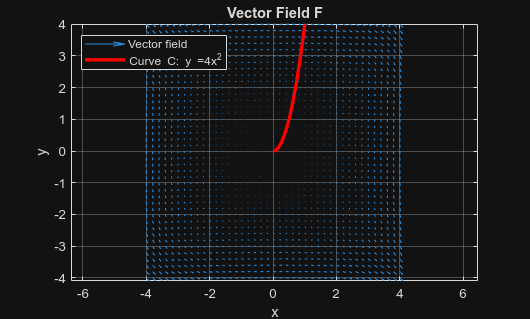

%Define de grid of points (x,y)
[x,y] = meshgrid(-4:0.2:4);

%u is f_x, v is f_y from y
u = y.^2;
v = -x.^2;

% use command quiver
quiver(x,y,u,v,0.5);
hold on;

%add the parametrized curve C
t_vals = linspace(0,1,100);
x_curve = t_vals;
y_curve = 4 * t_vals.^2;
plot(x_curve,y_curve,'r-', 'LineWidth',2.5);

%add direction arrows along the curve
t_arrows = 0.2:0.2:0.8; %4 tiny arrows along the curve

for t = t_arrows
    %point on the curve
    xa = t;
    ya = 4 * t.^2;

    %tangent vector
    dx = 0.05;
    dy = 8*t*dx;

    %use quiver to draw the arrows along c
    quiver(xa,ya,dx,dy,0,'r','LineWidth',2,'MaxHeadSize',2);

end

%plot settings
xlabel("x");
ylabel("y");
title("Vector Field F");
legend({'Vector field', 'Curve C: y =4x^2'}...
    ,'Location', 'northwest');

%axes scales equal
axis equal;
%xlim([-2,2]);
%ylim ([-2,2]);
grid on;
hold off

## Exercise 2

clear;
clc;
close all;

F = (y^2, -x^2)

C: Straight from (0,0) ---> (1,4)

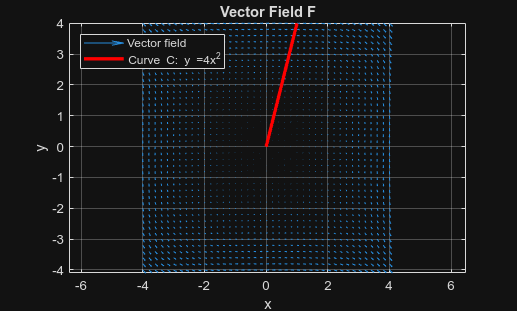

%Define de grid of points (x,y)
[x,y] = meshgrid(-4:0.2:4);

%u is f_x, v is f_y from y
u = y.^2;
v = -x.^2;

% use command quiver
quiver(x,y,u,v,0.5);
hold on;

%add the parametrized curve C
t_vals = linspace(0,1,100);
x_curve = t_vals;
y_curve = 4 * t_vals;
plot(x_curve,y_curve,'r-', 'LineWidth',2.5);

%add direction arrows along the curve
t_arrows = 0.2:0.2:0.8; %4 tiny arrows along the curve

for t = t_arrows
    %point on the curve
    xa = t;
    ya = 4 * t;

    %tangent vector
    dx = 0.05;
    dy = 4*dx;

    %use quiver to draw the arrows along c
    quiver(xa,ya,dx,dy,0,'r','LineWidth',2,'MaxHeadSize',2);

end

%plot settings
xlabel("x");
ylabel("y");
title("Vector Field F");
legend({'Vector field', 'Curve C: y =4x^2'}...
    ,'Location', 'northwest');

%axes scales equal
axis equal;
%xlim([-2,2]);

## Exercise 5

clear; close all; clc;

Parametrized helix

%parametrized helix
t = linspace(0,2*pi,500)

t =          0    0.0126    0.0252    0.0378    0.0504    0.0630    0.0755    0.0881    0.1007    0.1133    0.1259    0.1385    0.1511    0.1637    0.1763    0.1889    0.2015    0.2141    0.2266    0.2392    0.2518    0.2644    0.2770    0.2896    0.3022    0.3148    0.3274    0.3400    0.3526    0.3652    0.3777    0.3903    0.4029    0.4155    0.4281    0.4407    0.4533    0.4659    0.4785    0.4911    0.5037    0.5163    0.5288    0.5414    0.5540    0.5666    0.5792    0.5918    0.6044    0.6170


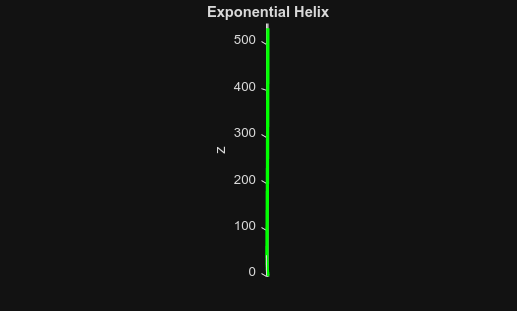

x = cos(t);
y = sin(t);
z = exp(t);

%plot the curve
figure;
plot3(x, y, z, 'g-','LineWidth', 2.5);
hold on;

%plot settings
xlabel('x');
ylabel('y');
zlabel('z');
title('Exponential Helix');
grid on;
axis equal;
view(45,30); %starting 3D angle

zlim([0, exp(2*pi)+10]);
hold off

## Electric field of a positive point charge

clear; close all; clc;

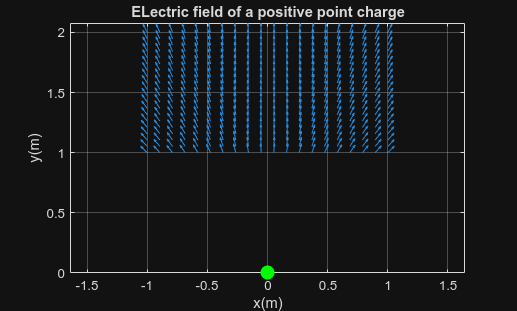

%constants
k = 9e9;
q = 1e-9;

%define the grid
x = linspace(-1,1,20);
y = linspace(1,2,20);
[X,Y] = meshgrid(x,y);

%define the distance from q
R = sqrt(X.^2 + Y.^2);
%avoid the origin (div by 0)
R ( R==0 ) = eps;

%define electric field, E_x, E_y
E_mag = k * q ./ R.^2;
Ex = E_mag .* (X./R);
Ey = E_mag .* (Y./R);

%normalize vectors
Ex_Norm = Ex ./ sqrt(Ex.^2 + Ey.^2);
Ey_Norm = Ey ./ sqrt(Ex.^2 + Ey.^2);

%plotting
figure;
quiver(X,Y,Ex_Norm, Ey_Norm, 0.7);
hold on;

%draw the point charge in green
plot(0,0,'go','MarkerSize', 10, 'MarkerFaceColor','g');

%formatting
axis equal;
xlabel("x(m)");
ylabel("y(m)");
title("ELectric field of a positive point charge");
grid on;
hold off